# E7

# Segmentació de la imatge

### Watershed

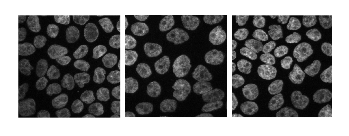

I = rgb2gray(imread("cellsegmentationcompetition.png"));
imshow(I);

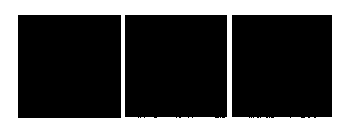

BW = I > 250;
M = false(size(I)); M(:,1) = 1; M(:,end) = 1; M(1,:) = 1; M(end,:) = 1;
REC = imreconstruct(M,BW);
imshow(REC);

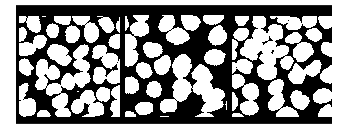

REC = imdilate(REC,strel("square",5));
I = I - 255*uint8(REC);

I = medfilt2(I,[3 3]);
BW = I > 16;
BW = imopen(BW,strel("square",3));
imshow(BW);

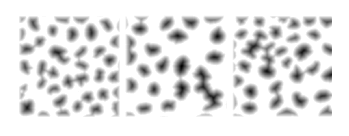


TD = -bwdist(not(BW),"quasi-euclidean");
TD = medfilt2(TD,[9 9]);
imshow(TD,[]);

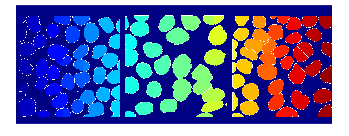

TD(not(BW)) = -Inf;  % per evitar la propagació de l'aigua en el Background
WS = watershed(TD);

IB = WS == 0;

RGB = label2rgb(WS);
imshow(RGB);

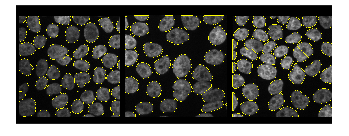


RGB2 = imoverlay(I,IB);
imshow(RGB2);

### Exercici Cornea

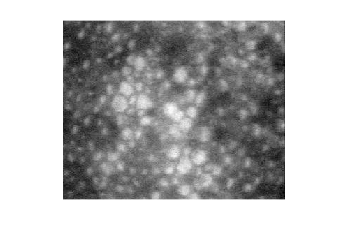

I = imread("cornea.tif");
imshow(I);

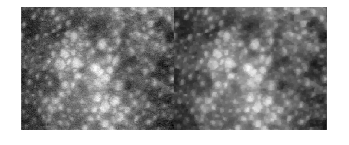



%filtrat
SE = ones(3,3);
IF = imopen(I,SE);
IF = imclose(IF,SE);
montage({I,IF});

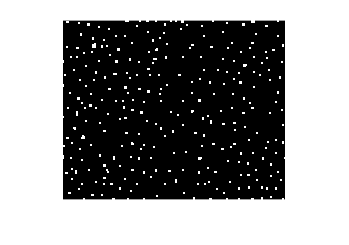


% maxims regionals
MR = imregionalmax(IF);
imshow(MR);

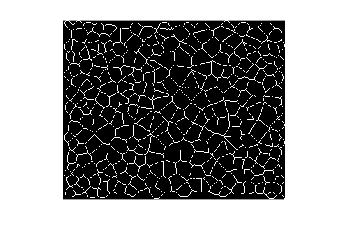


% SKIZ
SK = bwskel(not(MR));
SKIZ = bwmorph(SK,'spur',Inf);
% hit and miss
SKIZ = SKIZ & not(bwhitmiss(SKIZ, [-1 -1 -1; -1 1 -1; -1 -1 -1]));
imshow(SKIZ);

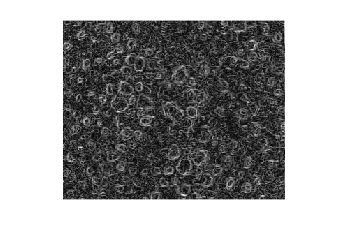


% imatge gradient
G = imgradient(I);
imshow(G,[]);

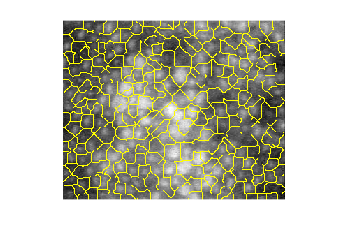


% Grad = uint8(imgradient(I))
% 

% Watershed
TD = -bwdist(not(MR),"quasi-euclidean");
%TD = medfilt2(TD,[1 1]);
WS = watershed(TD);
IB = WS == 0;

RGB = imoverlay(I,IB);
imshow(RGB);

## Segmentació per color

#### Simplificar el nombre de colors

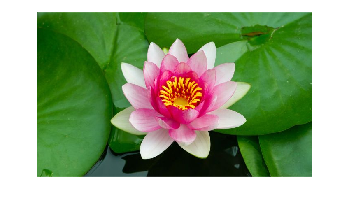

I = imread('nenufar.jpg');
imshow(I);

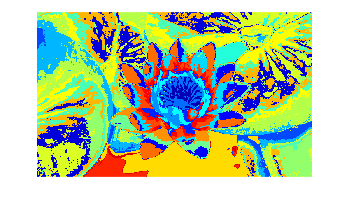

[f c p] = size(I);

R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

O = [R(:), G(:), B(:)];
[C, Centroide] = kmeans(double(O),25);  % segon paràmetre indica el nombre de classes
C = reshape(C,[f c]);
RGB = label2rgb(C);
imshow(RGB);

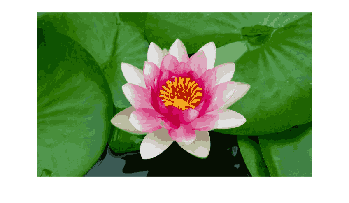


RGB2 = I;
for i = 1:f
    for j = 1:c
        rgb = Centroide(C(i,j),:);
        RGB2(i,j,1) = uint8(rgb(1));
        RGB2(i,j,2) = uint8(rgb(2));
        RGB2(i,j,3) = uint8(rgb(3));
    end
end
imshow(RGB2);